## Import transder functions from Simulink models

### Elevation pod

Elevation_pod_model ='Pod_elev_plant_linear';
io(1)=linio('Pod_elev_plant_linear/Engine_current_input',1,'input');
io(2)=linio('Pod_elev_plant_linear/Gyro_out_switch',1,'output');
simulation_POD_Elevation_plant_to_gyro = linearize(Elevation_pod_model,io);
io(1)=linio('Pod_elev_plant_linear/Dist_input',1,'input');
simulation_POD_Elevation_plant_from_dist_to_gyro = linearize(Elevation_pod_model,io);

tf_epod_current_gyro=tf(simulation_POD_Elevation_plant_to_gyro);
tf_epod_dist_gyro=tf(simulation_POD_Elevation_plant_from_dist_to_gyro);
tf_epod_inv_plant = 1/tf_epod_current_gyro;
tf_feed_forward_POD_elev_dist = tf(-tf_epod_dist_gyro/tf_epod_current_gyro);

[r_epod_inv_plant,p_epod_inv_plant,k_epod_inv_plant] = residue(tf_epod_inv_plant.Numerator{1,1},tf_epod_inv_plant.Denominator{1,1});
linear_epod_inv_plant = tf(r_epod_inv_plant(1),[1,-p_epod_inv_plant(1)]); 

[r_feed_pod_elev,p_feed_pod_elev,k_feed_pod_elev] = residue(tf_feed_forward_POD_elev_dist.Numerator{1,1},tf_feed_forward_POD_elev_dist.Denominator{1,1});
linear_feed_forward_POD_elev_dist = tf(r_feed_pod_elev(1),[1,-p_feed_pod_elev(1)]); 

linear_feed_forward_POD_elev_dist = tf((2.643e-11/132.5)/(s/132.5));

### Traverse pod

trav_pod_model ='Pod_trav_plant_linear';
io(1)=linio('Pod_trav_plant_linear/In_engine_current',1,'input');
io(2)=linio('Pod_trav_plant_linear/MS_gyro_velocity',1,'output');
simulation_POD_trav_plant_to_gyro = linearize(trav_pod_model,io);
io(1)=linio('Pod_trav_plant_linear/MS_engine_velocity',1,'input');
simulation_POD_trav_plant_from_dist_to_gyro = linearize(trav_pod_model,io);

tf_tpod_current_gyro=tf(simulation_POD_trav_plant_to_gyro);
tf_tpod_dist_gyro=tf(simulation_POD_trav_plant_from_dist_to_gyro);
tf_tpod_inv_plant = 1/tf_epod_current_gyro;
tf_feed_forward_POD_trav_dist = tf(-tf_tpod_dist_gyro/tf_tpod_current_gyro);

[r_tpod_inv_plant,p_tpod_inv_plant,k_tpod_inv_plant] = residue(tf_tpod_inv_plant.Numerator{1,1},tf_tpod_inv_plant.Denominator{1,1});
linear_tpod_inv_plant = tf(r_tpod_inv_plant(1),[1,-p_tpod_inv_plant(1)]); 

[r_feed_pod_trav,p_feed_pod_trav,k_feed_pod_trav] = residue(tf_feed_forward_POD_trav_dist.Numerator{1,1},tf_feed_forward_POD_trav_dist.Denominator{1,1});
linear_feed_forward_POD_trav_dist = tf(r_feed_pod_trav(1),[1,-p_feed_pod_trav(1)]); 

### Elevation Gun

Elevation_Gun_model = 'Gun_elev_plant_linear';
io(1)=linio('Gun_elev_plant_linear/Engine_current_input',1,'input');
io(2)=linio('Gun_elev_plant_linear/Gyro_output_switch',1,'output');
simulation_GUN_Elevation_plant_to_gyro = linearize(Elevation_Gun_model,io);

io(1)=linio('Gun_elev_plant_linear/Dist_input',1,'input');
simulation_GUN_Elevation_plant_from_dist_to_gyro = linearize(Elevation_Gun_model,io);

io(1)=linio('Gun_elev_plant_linear/Engine_current_input',1,'input');
io(2)=linio('Gun_elev_plant_linear/Engine_Velocity_out_switch',1,'output');
simulation_GUN_Elevation_plant_to_engineV = linearize(Elevation_Gun_model,io);

tf_egun_current_gyro=tf(simulation_GUN_Elevation_plant_to_gyro);
tf_egun_current_engineV=tf(simulation_GUN_Elevation_plant_to_engineV);
tf_egun_dist_gyro=tf(simulation_GUN_Elevation_plant_from_dist_to_gyro);
tf_egun_inv_plant = 1/tf_egun_current_gyro;

[r_egun_inv_plant,p_egun_inv_plant,k_egun_inv_plant] = residue(tf_egun_inv_plant.Numerator{1,1},tf_egun_inv_plant.Denominator{1,1});
linear_egun_inv_plant = tf(r_egun_inv_plant(1),[1,-p_egun_inv_plant(1)]); 

tf_feed_forward_GUN_elev_dist = tf(-tf_egun_dist_gyro/tf_egun_current_gyro);
[r_feed_gun_elev,p_feed_gun_elev,k_feed_gun_elev] = residue(tf_feed_forward_GUN_elev_dist.Numerator{1,1},tf_feed_forward_GUN_elev_dist.Denominator{1,1});
linear_feed_forward_GUN_elev_dist = tf(r_feed_gun_elev(1),[1,-p_feed_gun_elev(1)]); 

### Traverse Gun

Trav_Gun_model = 'Gun_trav_plant_linear';
io(1)=linio('Gun_trav_plant_linear/Engine_current_input',1,'input');
io(2)=linio('Gun_trav_plant_linear/Gyro_output_switch',1,'output');
simulation_GUN_trav_plant_to_gyro = linearize(Trav_Gun_model,io);

io(1)=linio('Gun_trav_plant_linear/Dist_input',1,'input');
simulation_GUN_trav_plant_from_dist_to_gyro = linearize(Trav_Gun_model,io);

io(1)=linio('Gun_trav_plant_linear/Engine_current_input',1,'input');
io(2)=linio('Gun_trav_plant_linear/Engine_Velocity_out_switch',1,'output');
simulation_GUN_trav_plant_to_engineV = linearize(Trav_Gun_model,io);

tf_tgun_current_gyro=tf(simulation_GUN_trav_plant_to_gyro);
tf_tgun_current_engineV=tf(simulation_GUN_trav_plant_to_engineV);
tf_tgun_dist_gyro=tf(simulation_GUN_trav_plant_from_dist_to_gyro);
tf_tgun_inv_plant = 1/tf_tgun_current_gyro;

[r_tgun_inv_plant,p_tgun_inv_plant,k_tgun_inv_plant] = residue(tf_tgun_inv_plant.Numerator{1,1},tf_tgun_inv_plant.Denominator{1,1});
linear_tgun_inv_plant = tf(r_tgun_inv_plant(1),[1,-p_tgun_inv_plant(1)]); 

tf_feed_forward_trav_elev_dist=tf(-tf_tgun_dist_gyro/tf_tgun_current_gyro);
[r_feed_gun_trav,p_feed_gun_trav,k_feed_gun_trav] = residue(tf_feed_forward_trav_elev_dist.Numerator{1,1},tf_feed_forward_trav_elev_dist.Denominator{1,1});
linear_feed_forward_GUN_trav_dist = tf(r_feed_gun_trav(1),[1,-p_feed_gun_trav(1)]); 

### Plots

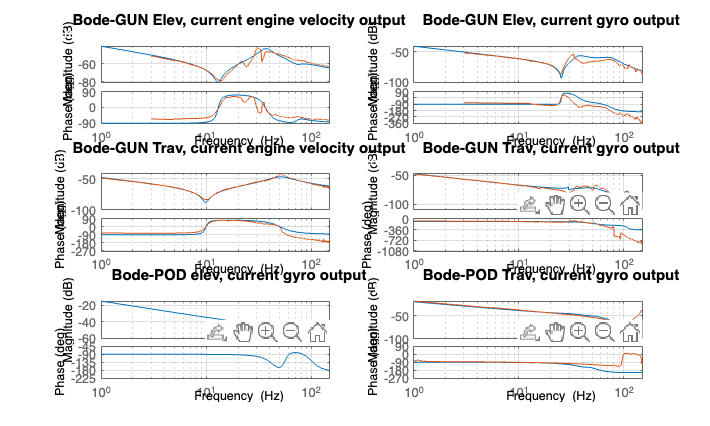

figure('Position', [10 10 1000 600]);

elev_gyro_plant = load("elevation_gyro_plant.mat");
ele_gyr_pla_mes = frd(elev_gyro_plant.o2i1,elev_gyro_plant.o2i1x,"FrequencyUnit","Hz");
trav_gyro_plant = load("trav_gyro_plant.mat");
tra_gyr_pla_mes = frd(trav_gyro_plant.o2i1,trav_gyro_plant.o2i1x,"FrequencyUnit","Hz");
elev_tacho_plant = load("elevation_tacho_plant.mat");
ele_tac_pla_mes = frd(elev_tacho_plant.o2i1,elev_tacho_plant.o2i1x,"FrequencyUnit","Hz");
trav_tacho_plant = load("trav_tacho_plant.mat");
tra_tac_pla_mes = frd(trav_tacho_plant.o2i1,trav_tacho_plant.o2i1x,"FrequencyUnit","Hz");
trav_tacho_plant_pod = load("podTrPlant.mat");
tra_tac_pla_mes_pod = frd(trav_tacho_plant_pod.o2i1,trav_tacho_plant_pod.o2i1x,"FrequencyUnit","Hz");


sub_plot_rows=3;
sub_plot_col=2;


opts = bodeoptions('cstprefs');
opts.FreqUnits = 'Hz';
opts.XLabel.FontSize = 10;
opts.YLabel.FontSize = 10;
opts.InputLabels.Color='white';
opts.Grid='on';
opts.Xlim={[1,150]};
font_title_size=12;


%plot bode_gun_elevation

subplot(sub_plot_rows,sub_plot_col,1)
bodeplot(tf_egun_current_engineV,opts)
hold on
bodeplot(ele_tac_pla_mes)

title('Bode-GUN Elev, current engine velocity output', 'FontSize', font_title_size)

subplot(sub_plot_rows,sub_plot_col,2)
bodeplot(tf_egun_current_gyro,opts)
hold on
bodeplot(ele_gyr_pla_mes)
title('Bode-GUN Elev, current gyro output', 'FontSize', font_title_size)

% subplot(sub_plot_rows,sub_plot_col,3)
% bodeplot(tf_egun_inv_plant,opts)
% title('Bode-GUN Elev, inverse current gyro output', 'FontSize', font_title_size)
% 
% subplot(sub_plot_rows,sub_plot_col,4)
% bodeplot(tf_egun_dist_gyro,opts)
% title('Bode-GUN Elev, Disturbances input gyro output', 'FontSize', font_title_size)

%plot bode_gun_traverse

subplot(sub_plot_rows,sub_plot_col,3)
bodeplot(tf_tgun_current_engineV,opts)
hold on
bodeplot(tra_tac_pla_mes)
title('Bode-GUN Trav, current engine velocity output', 'FontSize', font_title_size)

subplot(sub_plot_rows,sub_plot_col,4)
bodeplot(tf_tgun_current_gyro,opts)
hold on
bodeplot(tra_gyr_pla_mes)
title('Bode-GUN Trav, current gyro output', 'FontSize', font_title_size)
subplot(sub_plot_rows,sub_plot_col,5)
bodeplot(simulation_POD_Elevation_plant_to_gyro,opts)
% hold on
% bodeplot(tra_gyr_pla_mes)
title('Bode-POD elev, current gyro output', 'FontSize', font_title_size)



subplot(sub_plot_rows,sub_plot_col,6)
bodeplot(simulation_POD_trav_plant_to_gyro,opts)
hold on
bodeplot(tra_tac_pla_mes_pod)
title('Bode-POD Trav, current gyro output', 'FontSize', font_title_size)

% subplot(sub_plot_rows,sub_plot_col,7)
% bodeplot(tf_tgun_inv_plant,opts)
% title('Bode-GUN Trav, inverse current gyro output', 'FontSize', font_title_size)
% 
% subplot(sub_plot_rows,sub_plot_col,8)
% bodeplot(tf_tgun_dist_gyro,opts)
% title('Bode-GUN Trav, Disturbances input gyro output', 'FontSize', font_title_size)

%plot bode_pod_traverse

% subplot(sub_plot_rows,sub_plot_col,9)
% bodeplot(tf_epod_current_gyro,opts)
% title('Bode-Pod Elev, current gyro output', 'FontSize', font_title_size)
% 
% subplot(sub_plot_rows,sub_plot_col,10)
% bodeplot(tf_epod_inv_plant,opts)
% title('Bode-Pod Elev, Inverse current gyro output', 'FontSize', font_title_size)